[cbAudio, cbFs] = audioread('common_blackbird_long.wav');
% convert to mono
cbAudio = mono(cbAudio);
% trim the first bit of silence
cbAudio = cbAudio(1.5*cbFs:end);
% normalize
cbAudio = normalize(cbAudio)/8;

cb = cbAudio;
fs = cbFs;

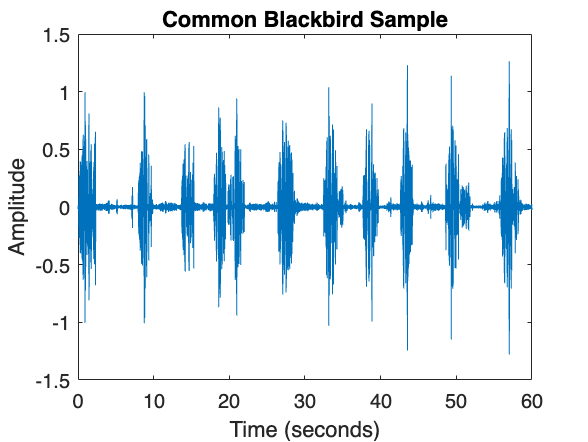

plot((0:numel(cbAudio)-1)/cbFs,cbAudio)
title('Common Blackbird Sample')
xlabel('Time (seconds)')
ylabel('Amplitude')

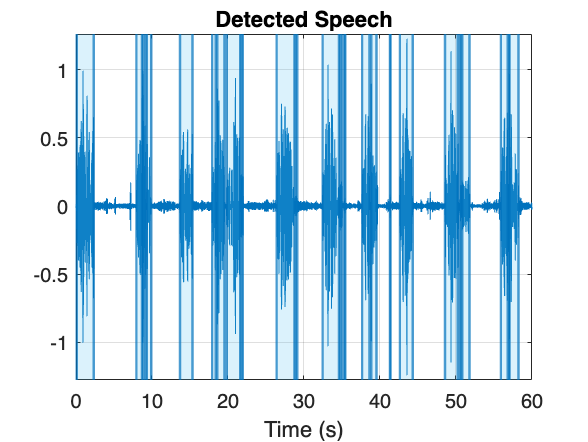

detectSpeech(cb, fs);

callIndices = detectSpeech(cb, fs);
callSignal = [];
for ii = 1:size(callIndices,1)
    callSignal = [callSignal;cb(callIndices(ii,1):callIndices(ii,2))];
end

sound(callSignal,fs)

% segment duration in seconds
segmentDuration = 3;
segmentLength = segmentDuration * fs;
totalSegments = floor(length(callSignal)/segmentLength);